# Chemical Reaction

Instructions are in the task pane to the left. Complete and submit each task one at a time.

## Task 1

Define time interval.

tRange = [0 3];

## Task 2

Define initial condition.

Y0 = [100;0];

## Task 3 

Solve the system of ODEs. The system is implemented in the local function `reactionODE`.

[tSol,YSol] = ode45(@reactionODE,tRange,Y0)

tSol =          0
    0.0025
    0.0050
    0.0075
    0.0100
    0.0226
    0.0352
    0.0477
    0.0603
    0.1231


YSol =   100.0000         0
   99.9999    0.0001
   99.9999    0.0001
   99.9998    0.0002
   99.9998    0.0002
   99.9995    0.0005
   99.9993    0.0007
   99.9990    0.0010
   99.9988    0.0012
   99.9975    0.0025


## Task 4

Extract the chemical *x*.

x = YSol(:,1)

x =   100.0000
   99.9999
   99.9999
   99.9998
   99.9998
   99.9995
   99.9993
   99.9990
   99.9988
   99.9975


## Task 5

Extract the chemical *y*.

y = YSol(:,2)

y =          0
    0.0001
    0.0001
    0.0002
    0.0002
    0.0005
    0.0007
    0.0010
    0.0012
    0.0025


**Visualize *****x***** and *****y***

Do not edit. This code visualizes the solution.

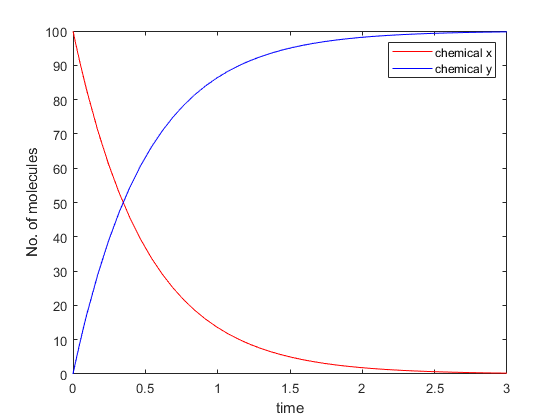

plot(tSol,x,'r')
hold on
plot(tSol,y,'b')
hold off

% Annotate plot
legend('chemical x','chemical y')
xlabel('time')
ylabel('No. of molecules')

**ODE function**

Do not edit. This code defines the ODE function for the system of ODEs

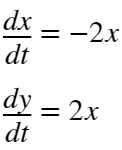

function dYdt = reactionODE(t,Y)
    x = Y(1); % chemical x
    y = Y(2); % chemical y
    dxdt = -2*x;
    dydt = 2*x;
    dYdt = [dxdt;dydt];
end